# `ClockChart`** Examples**

**Overview**

The `ClockChart` creates an analog clock backed by a MATLAB `timer` object for timekeeping. This chart illustrates the use of timer objects to schedule chart updates. The timer's callback property `TimerFcn` is implemented as a private chart method. The chart also needs to manage the lifecycle of the timer by deleting it when the chart is deleted. We do not have direct access to the chart's destructor method, so the approach is to create a listener to the chart event `ObjectBeingDestroyed`.

The listener callback `onChartDeleted` is implemented as a private chart method, and is responsible for safely disposing of the timer.

**Resources**

[Open](matlab: edit(fullfile(catalogRoot, "+example", "ClockChartExamples.mlx"))) this Live Script to run and interact with the examples shown below.

[View](matlab: edit(fullfile(catalogRoot, "+chart", "Cylinder.m"))) the source code for the `ClockChart`.

Documentation for:

- [`timer`](matlab: doc timer): Schedule execution of MATLAB commands

- [`patch`](matlab: doc patch): Create patches of colored polygons

- [`line`](matlab: doc line): Create primitive line

## Create a figure for the chart.

f = exampleFigure( "Name", "ClockChart Example" );

## Create the chart, specifying the parent.

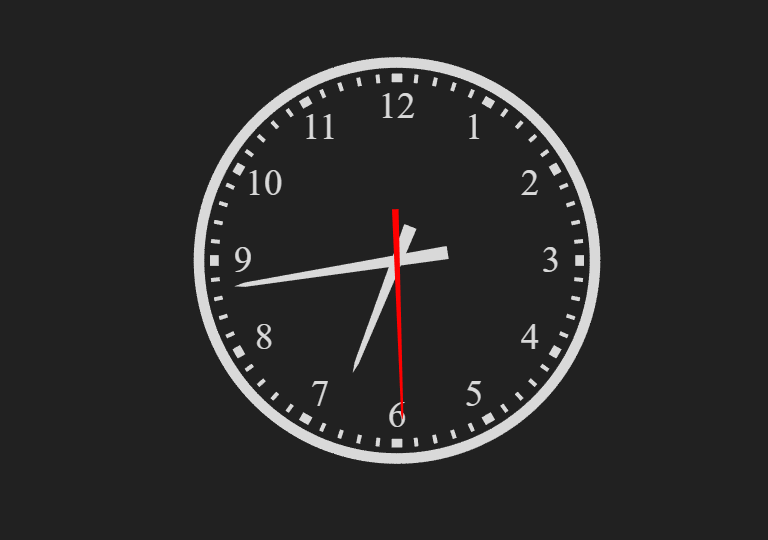

CC = ClockChart( "Parent", f );

*Copyright 2024-2025 The MathWorks, Inc.*